Загрузим географические координаты станций (постов)

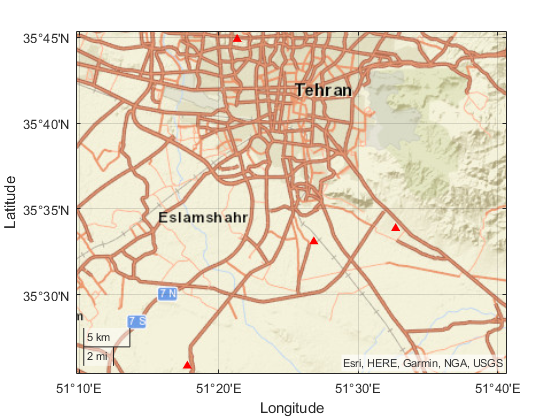

S = read_stations("Stations 2019-10-23.xlsx");
% S = read_stations("Stations 2021-09-20.xlsx");
show_stations(S)

Переведем географические координаты в топоцентрические 

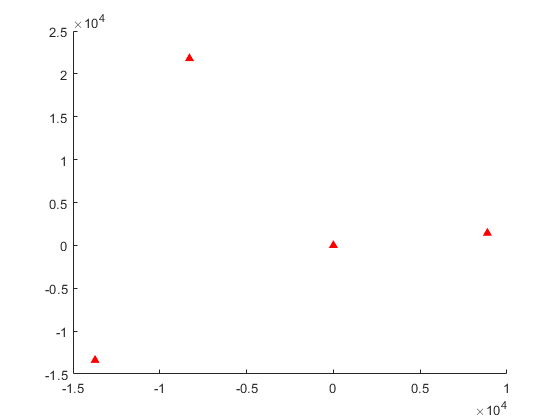

L = stations2local(S);
show_local(L);

Загрузим сами данные. Преобразуем их в timetable и оставим только интересущие нас столбцы.

T = readtable("TDOA 2019-10-23.csv");
% T = readtable("TDOA 2021-09-20.csv");
T.Date = datetime(T.Time,'ConvertFrom','epochtime','TicksPerSecond',1e3);
T.Base = T.Post1 .* 10 + T.Post2;
D = table2timetable(T);
D = D(:, ["Base", "Amplitude", "Difference", "Duration", "Frequency"]);

Посмотрим, что получилось

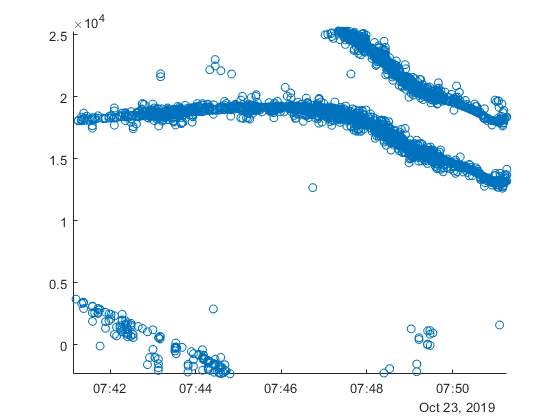

figure
scatter(D.Date, D.Difference);

Разделим все данные на куски по базам (каждая база в отдельной таблице)

D41 = D(D.Base == 41, :);
D42 = D(D.Base == 42, :);
D43 = D(D.Base == 43, :);
D21 = D(D.Base == 21, :);
D23 = D(D.Base == 23, :);

Произведем чистку входных данных - удалим заведомо некорректные данные по амплитуде и длительности (пока не делается)

% этого делать (пока) не будем

Удалим информацию, которая в дальнейших вычислениях использоваться не будет

D41 = removevars(D41,["Base", "Amplitude","Duration", "Frequency"]);
D42 = removevars(D42,["Base", "Amplitude","Duration", "Frequency"]);
D43 = removevars(D43,["Base", "Amplitude","Duration", "Frequency"]);
D21 = removevars(D21,["Base", "Amplitude","Duration", "Frequency"]);
D23 = removevars(D23,["Base", "Amplitude","Duration", "Frequency"]);

Перед началом обработки снова посмотрим на исходные данные и их распределение по базам 

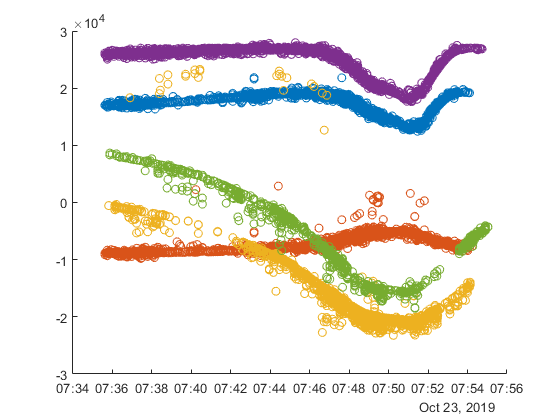

figure
hold on
scatter(D41.Date, D41.Difference);
scatter(D42.Date, D42.Difference);
scatter(D43.Date, D43.Difference);
scatter(D21.Date, D21.Difference);
scatter(D23.Date, D23.Difference);
hold off

Обработаем дубликаты - возьмем только первый элемент

uniqueTimes = unique(D41.Date); D41 = retime(D41,uniqueTimes);
uniqueTimes = unique(D42.Date); D42 = retime(D42,uniqueTimes);
uniqueTimes = unique(D43.Date); D43 = retime(D43,uniqueTimes);
uniqueTimes = unique(D21.Date); D21 = retime(D21,uniqueTimes);
uniqueTimes = unique(D23.Date); D23 = retime(D23,uniqueTimes);


Удалим сильные выбросы, которые портят усреднение

D41rmoutliers = rmoutliers(D41, 'percentiles', [0.5 99.5]);
D42rmoutliers = rmoutliers(D42, 'percentiles', [0.5 99.5]);
D43rmoutliers = rmoutliers(D43, 'percentiles', [0.5 99.5]);
D21rmoutliers = rmoutliers(D21, 'percentiles', [0.5 99.5]);
D23rmoutliers = rmoutliers(D23, 'percentiles', [0.5 99.5]);

Удалим обычные выбросы, усредняя


D41rmoutliers = rmoutliers(D41rmoutliers, 'movmean', seconds(10));
D42rmoutliers = rmoutliers(D42rmoutliers, 'movmean', seconds(10));
D43rmoutliers = rmoutliers(D43rmoutliers, 'movmean', seconds(10));
D21rmoutliers = rmoutliers(D21rmoutliers, 'movmean', seconds(10));
D23rmoutliers = rmoutliers(D23rmoutliers, 'movmean', seconds(10));

Посмотрим, что получилось (голубые точки теперь удалены, их больше нет)

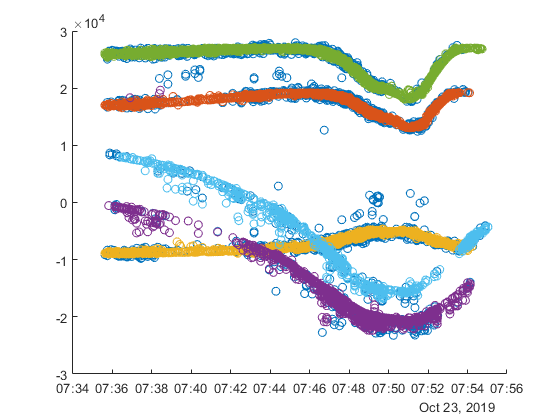

figure
hold on
scatter(D.Date, D.Difference)
scatter(D41rmoutliers.Date, D41rmoutliers.Difference)
scatter(D42rmoutliers.Date, D42rmoutliers.Difference)
scatter(D43rmoutliers.Date, D43rmoutliers.Difference)
scatter(D21rmoutliers.Date, D21rmoutliers.Difference)
scatter(D23rmoutliers.Date, D23rmoutliers.Difference)
hold off

После удаления выбросов остаток точек для обработки выглядит следующим образом

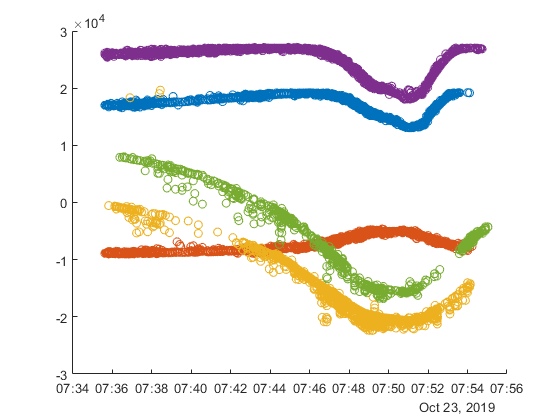

figure
hold on
scatter(D41rmoutliers.Date, D41rmoutliers.Difference)
scatter(D42rmoutliers.Date, D42rmoutliers.Difference)
scatter(D43rmoutliers.Date, D43rmoutliers.Difference)
scatter(D21rmoutliers.Date, D21rmoutliers.Difference)
scatter(D23rmoutliers.Date, D23rmoutliers.Difference)
hold off

Рекалибруем каждую базу посекундно

D41retime = retime(D41rmoutliers,'secondly', 'linear');
D42retime = retime(D42rmoutliers,'secondly', 'linear');
D43retime = retime(D43rmoutliers,'secondly', 'linear');
D21retime = retime(D21rmoutliers,'secondly', 'linear');
D23retime = retime(D23rmoutliers,'secondly', 'linear');


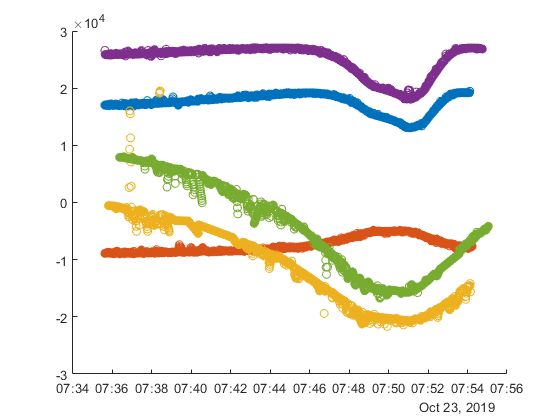

figure
hold on
scatter(D41retime.Date, D41retime.Difference)
scatter(D42retime.Date, D42retime.Difference)
scatter(D43retime.Date, D43retime.Difference)
scatter(D21retime.Date, D21retime.Difference)
scatter(D23retime.Date, D23retime.Difference)
hold off

Сгладим каждую базу фильтром Савицкого-Голея

D41smooth = smoothdata(D41retime, 'sgolay');
D42smooth = smoothdata(D42retime, 'sgolay');
D43smooth = smoothdata(D43retime, 'sgolay');
D21smooth = smoothdata(D21retime, 'sgolay');
D23smooth = smoothdata(D23retime, 'sgolay');

Синхронизируем базы между собой

Result = synchronize(D41smooth,D42smooth,D43smooth,D21smooth,...
    D23smooth,'union','fillwithmissing');

Посмотрим, что получилось

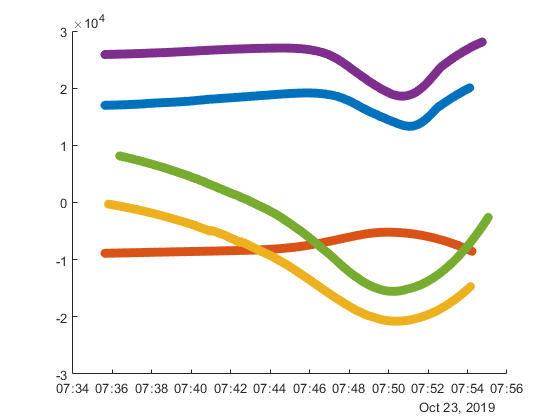

figure
hold on
scatter(Result.Date, Result.Difference_D41smooth);
scatter(Result.Date, Result.Difference_D42smooth);
scatter(Result.Date, Result.Difference_D43smooth);
scatter(Result.Date, Result.Difference_D21smooth);
scatter(Result.Date, Result.Difference_D23smooth);
hold off

То, что получилось на фоне того, что было

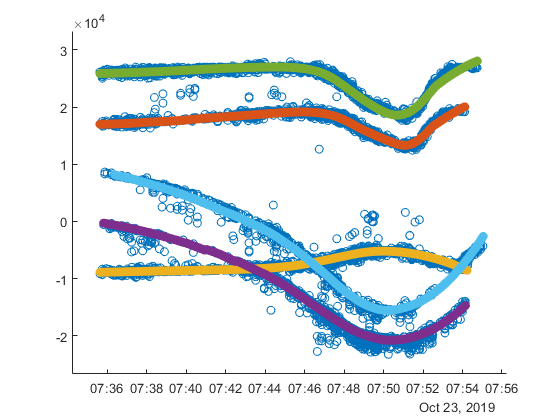

figure
hold on
scatter(D.Date, D.Difference)
scatter(Result.Date, Result.Difference_D41smooth);
scatter(Result.Date, Result.Difference_D42smooth);
scatter(Result.Date, Result.Difference_D43smooth);
scatter(Result.Date, Result.Difference_D21smooth);
scatter(Result.Date, Result.Difference_D23smooth);
hold off

Посчитаем топоцентрические координаты по разностям хода (для каждого значения решаем трёхмерную задачу)

[x, y, z] = calc_coords(L, Result(:,:));

Посмотрим, какой набор точек получился в трёхмерном пространстве. 

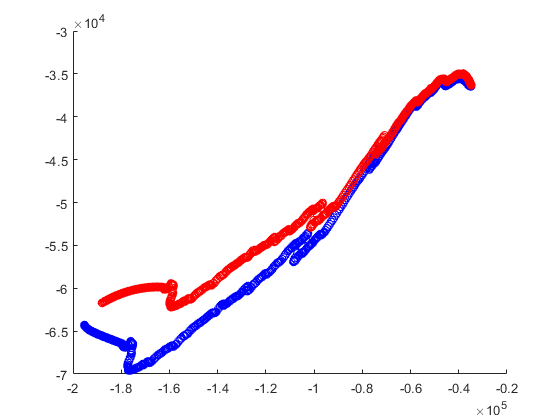

figure
hold on
scatter3(x(:,1),y(:,1),z(:,1), 'blue');
scatter3(x(:,2),y(:,2),z(:,2), 'red');
hold off

Переведем в географические координаты

[lat1,lon1,alt1] = local2latlon(x(:,1),y(:,1),z(:,1),[S.Latitude(4), S.Longitude(4), S.Altitude(4)]);
[lat2,lon2,alt2] = local2latlon(x(:,2),y(:,2),z(:,2),[S.Latitude(4), S.Longitude(4), S.Altitude(4)]);

Нарисуем на карте

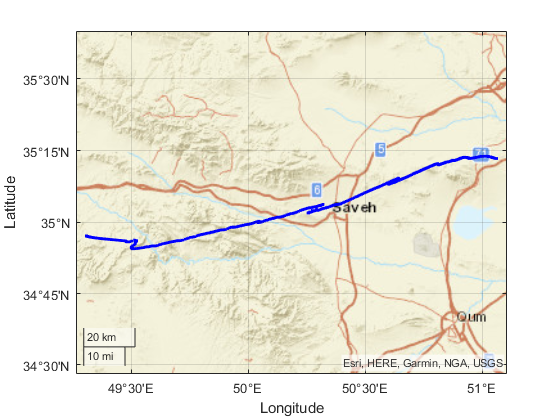

figure
geoscatter (lat1, lon1, '.', 'blue');
geobasemap streets

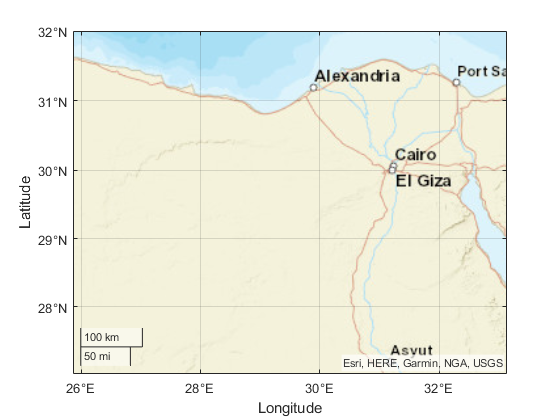

geoscatter (lat2, lon2, '.','red');
geobasemap streets

geolimits([27 32],[27 32])